# Natural Resources Management

# Final Project

addpath("utils\")

## Part 0. Data pre-processing

file = readmatrix("data\5. Jochenstein.csv");
data_precipitation = file(:,4); % [mm/d]
data_streamflow = file(:,5); % [m3/s]
data_temperature = file(:,6); % °C

### Dataset times

Total dataset total years and years used for training, taking 70% of the dataset

T = 365;
tr_length = 0.70;
years_total = length(file) / T

years_total = 27

years_tr = floor(years_total*tr_length)

years_tr = 18

### Dataset partition 

% Training dataset
x_tr = data_streamflow(1:T*years_tr);
u_tr = [data_precipitation(1:T*years_tr) data_temperature(1:T*years_tr)];
% Validation dataset
x_val = data_streamflow(T*years_tr+1:end);
u_val = [data_precipitation(T*years_tr+1:end) data_temperature(T*years_tr+1:end)];

### Cyclostationary  analysis

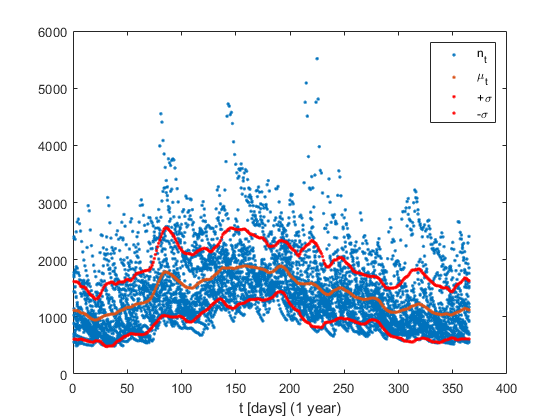

f = 5; 
N_tr = length(x_tr);
tt = repmat([1:T]', N_tr/T, 1);
% Moving Average
[mi, m] = moving_average(x_tr, T, f);
% Moving variance
[ma_var2, s2] = moving_average((x_tr - m).^2, T, f);
ma_var = ma_var2.^(1/2);
s = s2.^(1/2);
figure;
plot(tt, [x_tr, m], '.');
xlabel('t [days] (1 year)');
hold on;
% plot([1 : T], mi, 'g', 'LineWidth',.5);
plot(tt, m + s, '.r');
plot(tt, m - s, '.r');
legend('n_t', '\mu_t', '+\sigma', '-\sigma');

% legend('n_t', '\mu_t', '\mu_{cyclo}', '+\sigma', '-\sigma');

### Correlations

#### Streamflow - Precipitations

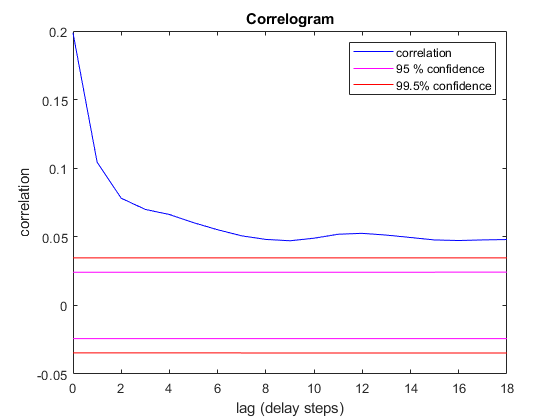

figure; correlogram(x_tr, u_tr(:,1), years_tr)

#### Streamflow - Temperature

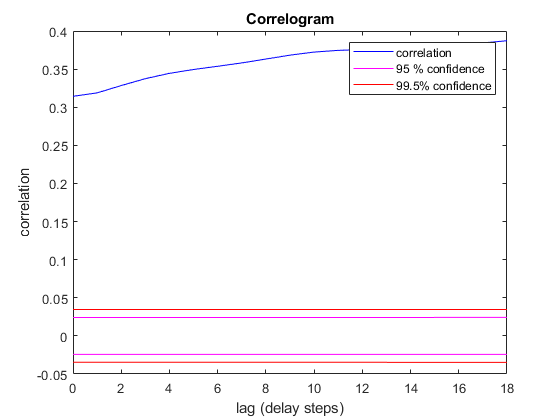

figure; correlogram(x_tr, u_tr(:,2), years_tr)

### Data normalization

f = 5; 
[x_norm, mean_x, sigma_x] = deseasonalize(x_tr, T, f);
[u_norm(:,1), mean_u(:,1), sigma_u(:,1)] = deseasonalize(u_tr(:,1), T, f);
[u_norm(:,2), mean_u(:,2), sigma_u(:,2)] = deseasonalize(u_tr(:,2), T, f);

[x_norm_val, mean_x_val, sigma_x_val] = deseasonalize(x_val, T, f);
[u_norm_val(:,1), mean_u_val(:,1), sigma_u_val(:,1)] = deseasonalize(u_val(:,1), T, f);
[u_norm_val(:,2), mean_u_val(:,2), sigma_u_val(:,2)] = deseasonalize(u_val(:,2), T, f);

### Correlations

#### Streamflow - Precipitations

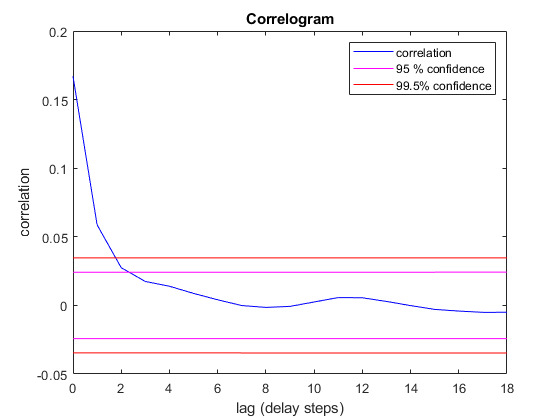

figure; correlogram(x_norm, u_norm(:,1), years_tr)

#### Streamflow - Temperature

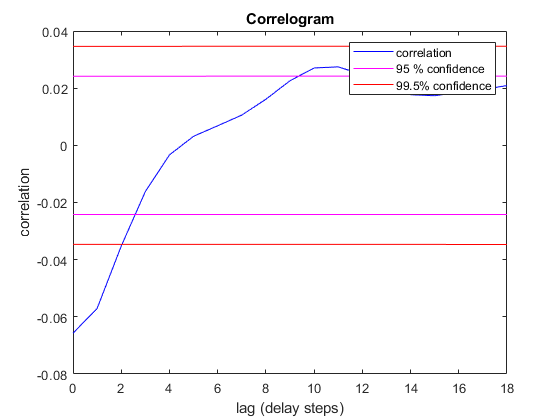

figure; correlogram(x_norm, u_norm(:,2), years_tr)

## Part 1. 1-day ahead forecast model

### Linear models

#### AR (n)

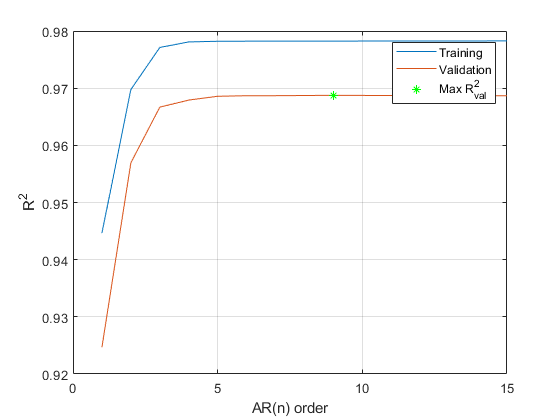

ar_iteation = 15;
r2_ar = nan(ar_iteation,1);
r2_ar_val = nan(ar_iteation,1);
r2_ar_val_max = 0;
ar_opt_idx = 0;
for i=1:ar_iteation
    [theta_ar_i, x_norm_ar] = trainAR(x_norm, i);
    x_norm_ar_val = estimateAR(x_norm_val, theta_ar_i, i);
    
%     Training
    r2_ar(i) = getR2Performance( ...
            x_tr, ...
            x_norm_ar, ...
            mean_x, ...
            sigma_x ...
        );
%     Validation
    r2_ar_val(i) = getR2Performance( ...
            x_val, ...
            x_norm_ar_val, ...
            mean_x_val, ...
            sigma_x_val ...
        );
    
    if r2_ar_val_max < r2_ar_val(i)
        theta_ar = theta_ar_i;
        ar_opt_idx = i;
        r2_ar_val_max = r2_ar_val(i);
    end
    
end
clear i
figure;
plot([r2_ar, r2_ar_val])
hold on 
plot (ar_opt_idx, r2_ar_val_max, '*g')
legend('Training','Validation','Max R^2_{val}')
xlabel('AR(n) order');ylabel('R^2');
grid on

#### Proper ARX (1,1)

y = x_norm(2:end);
M = [x_norm(1:end-1), u_norm(1:end-1,:)];
theta = M\y;
x_est = [x_norm(1); M*theta];
r2_arx = getR2Performance(x_tr, x_est, mean_x, sigma_x)

r2_arx = 0.9708

M_val = [x_norm_val(1:end-1), u_norm_val(1:end-1,:)];
x_est = [x_norm_val(1); M_val*theta];
r2_arx_val = getR2Performance(x_val, x_est, mean_x_val, sigma_x_val)

r2_arx_val = 0.9626

#### Improper ARX (1,1)

### Nonlinear models

#### Proper ANN

#### Improper ANN

#### CART

### Models comparison

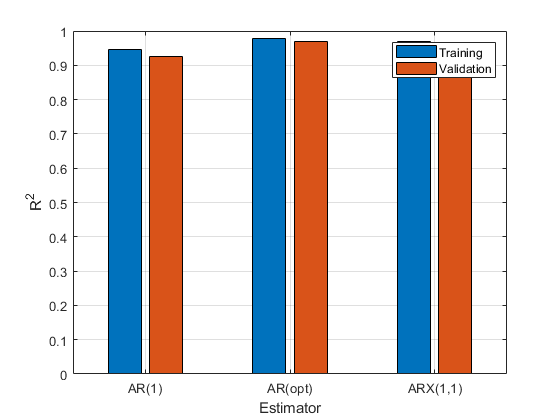

figure;
c = categorical({ ...
    'AR(1)', ...
    'AR(opt)', ...
    'ARX(1,1)', ...
    });
h = bar(c,[ ...
    r2_ar(1), r2_ar_val(1); ...
    r2_ar(ar_opt_idx), r2_ar_val(ar_opt_idx); ...
    r2_arx, r2_arx_val; ...
    ]);
set(h, {'DisplayName'}, {'Training','Validation'}')
xlabel('Estimator');ylabel('R^2');
legend()
grid on

## Part 2. Dam sizing impacts